% 准备区
clear;
clc;
addpath '.\semi-parameters'
warning off; clear; clc; config_fullconnect;

P = transform_parameters(opt_x);
friction_parameters = zeros(7, 5);
for joint = Joint(1, 1) : Joint(end, 1)
    friction_parameters(joint, :) = [[opt_x(71 + (joint - 1) * 4 : 74 + (joint - 1) * 4)]', [opt_x(99 + (joint - 1))]];
end

load('data\filtering_data_no_downsampling.mat');
q_filt_0 = q_filt;
qd_filt_0 = qd_filt;
qdd_filt_0 = qdd_filt;
t_filt_0 = t_filt;

load('data\filted_No1_excitation_trajectory.mat');
q_filt_1 = q_filt;
qd_filt_1 = qd_filt;
qdd_filt_1 = qdd_filt;
t_filt_1 = t_filt;

load('data\filted_No2_excitation_trajectory.mat');
q_filt_2 = q_filt;
qd_filt_2 = qd_filt;
qdd_filt_2 = qdd_filt;
t_filt_2 = t_filt;

load('data\filted_No3_excitation_trajectory.mat');
q_filt_3 = q_filt;
qd_filt_3 = qd_filt;
qdd_filt_3 = qdd_filt;
t_filt_3 = t_filt;

load('data\filted_No4_excitation_trajectory.mat');
q_filt_4 = q_filt;
qd_filt_4 = qd_filt;
qdd_filt_4 = qdd_filt;
t_filt_4 = t_filt;

load('data\filted_No5_excitation_trajectory.mat');
q_filt_5 = q_filt;
qd_filt_5 = qd_filt;
qdd_filt_5 = qdd_filt;
t_filt_5 = t_filt;

q_filt = [q_filt_0; q_filt_1; q_filt_2; q_filt_3; q_filt_4; q_filt_5];
qd_filt = [qd_filt_0; qd_filt_1; qd_filt_2; qd_filt_3; qd_filt_4; qd_filt_5];
qdd_filt = [qdd_filt_0; qdd_filt_1; qdd_filt_2; qdd_filt_3; qdd_filt_4; qdd_filt_5];
t_filt = [t_filt_0; t_filt_1; t_filt_2; t_filt_3; t_filt_4; t_filt_5];

clearvars q q_filt_0 q_filt_1 q_filt_2 q_filt_3 q_filt_4 q_filt_5 ...
          qd qd_filt_0 qd_filt_1 qd_filt_2 qd_filt_3 qd_filt_4 qd_filt_5 ...
          qdd qdd_filt_0 qdd_filt_1 qdd_filt_2 qdd_filt_3 qdd_filt_4 qdd_filt_5 ...
          t_filt_0 t_filt_1 t_filt_2 t_filt_3 t_filt_4 t_filt_5;

g = 9.80665;
[n_sample, ~] = size(q_filt);
T = zeros(n_sample, 7);
T_idy = zeros(n_sample, 7);

for k = 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);
    T(k, :) = t_filt(k, :);
    ww = compute_regression_matrix(q, qd, qdd, 0);

    T_idy(k,:) = ww * P';

    for i = 1 : 7
        T_idy(k, i) = T_idy(k, i) + compute_Stribeck_friction(qd(1, i), friction_parameters(i, :), gamma);
    end
end

## 代码-非参数部分：

工作流程如下：

- 制作数据集；

- 划分数据集 & 转换格式；

- 搭建LSTM神经网络；

- 训练神经网络；

- 验证神经网络；

- 验证模型效果；

### 第一步：制作数据集

num_sample_point = size(q_filt, 1);
database = zeros(num_factors * size(Joint, 1) , num_sample_point);
T_error = T - T_idy;
for frame = 1 : num_sample_point
    % 数据集结构
   database(:, frame) = [q_filt(frame, :)'; qd_filt(frame, :)'; qdd_filt(frame, :)'; T_error(frame, :)'];
end

### 第二步：划分数据集 & 转换格式

% 划分数据集
split = floor(num_sample_point * train_percent);
input_train = database(1 : (num_factors-1) * size(Joint, 1), 1 : split);
output_train = database((num_factors-1) * size(Joint, 1) + 1 : end, 1 : split);

input_test = database(1 : (num_factors-1) * size(Joint, 1), split + 1 : end);
output_test = database((num_factors-1)* size(Joint, 1) + 1 : end, split + 1 : end);

### 第三步：定义全连接神经网络

layers = [
    featureInputLayer((num_factors - 1) * size(Joint, 1))  % 建立输入层，使用featureInputLayer代替sequenceInputLayer

    fullyConnectedLayer(32)  % 第一个全连接层，输出节点数为32
    reluLayer                % ReLU激活层

    fullyConnectedLayer(16)  % 第二个全连接层，输出节点数为16
    reluLayer                % ReLU激活层

    fullyConnectedLayer(7)   % 全连接层，输出节点数为7，对应于输出的维度
    regressionLayer          % 回归层，用于回归问题
    ];

### 参数设置

options = trainingOptions('adam', ...            % Adam 梯度下降算法
    'MiniBatchSize', BatchSize, ...              % 批大小
    'MaxEpochs', Epochs, ...                     % 最大迭代次数
    'InitialLearnRate', 0.01, ...                % 初始学习率
    'LearnRateSchedule', 'piecewise', ...        % 学习率下降
    'LearnRateDropFactor', 0.5, ...              % 学习率下降因子
    'LearnRateDropPeriod', Epochs * 0.4, ...     % 经过X次训练后，学习率为InitialLearnRate * LearnRateDropFactor
    'Shuffle', 'every-epoch', ...                % 每次训练后训练打乱数据
    'Plots', 'training-progress', ...            % 画出曲线
    'Verbose', false);

### 第四步：训练神经网络

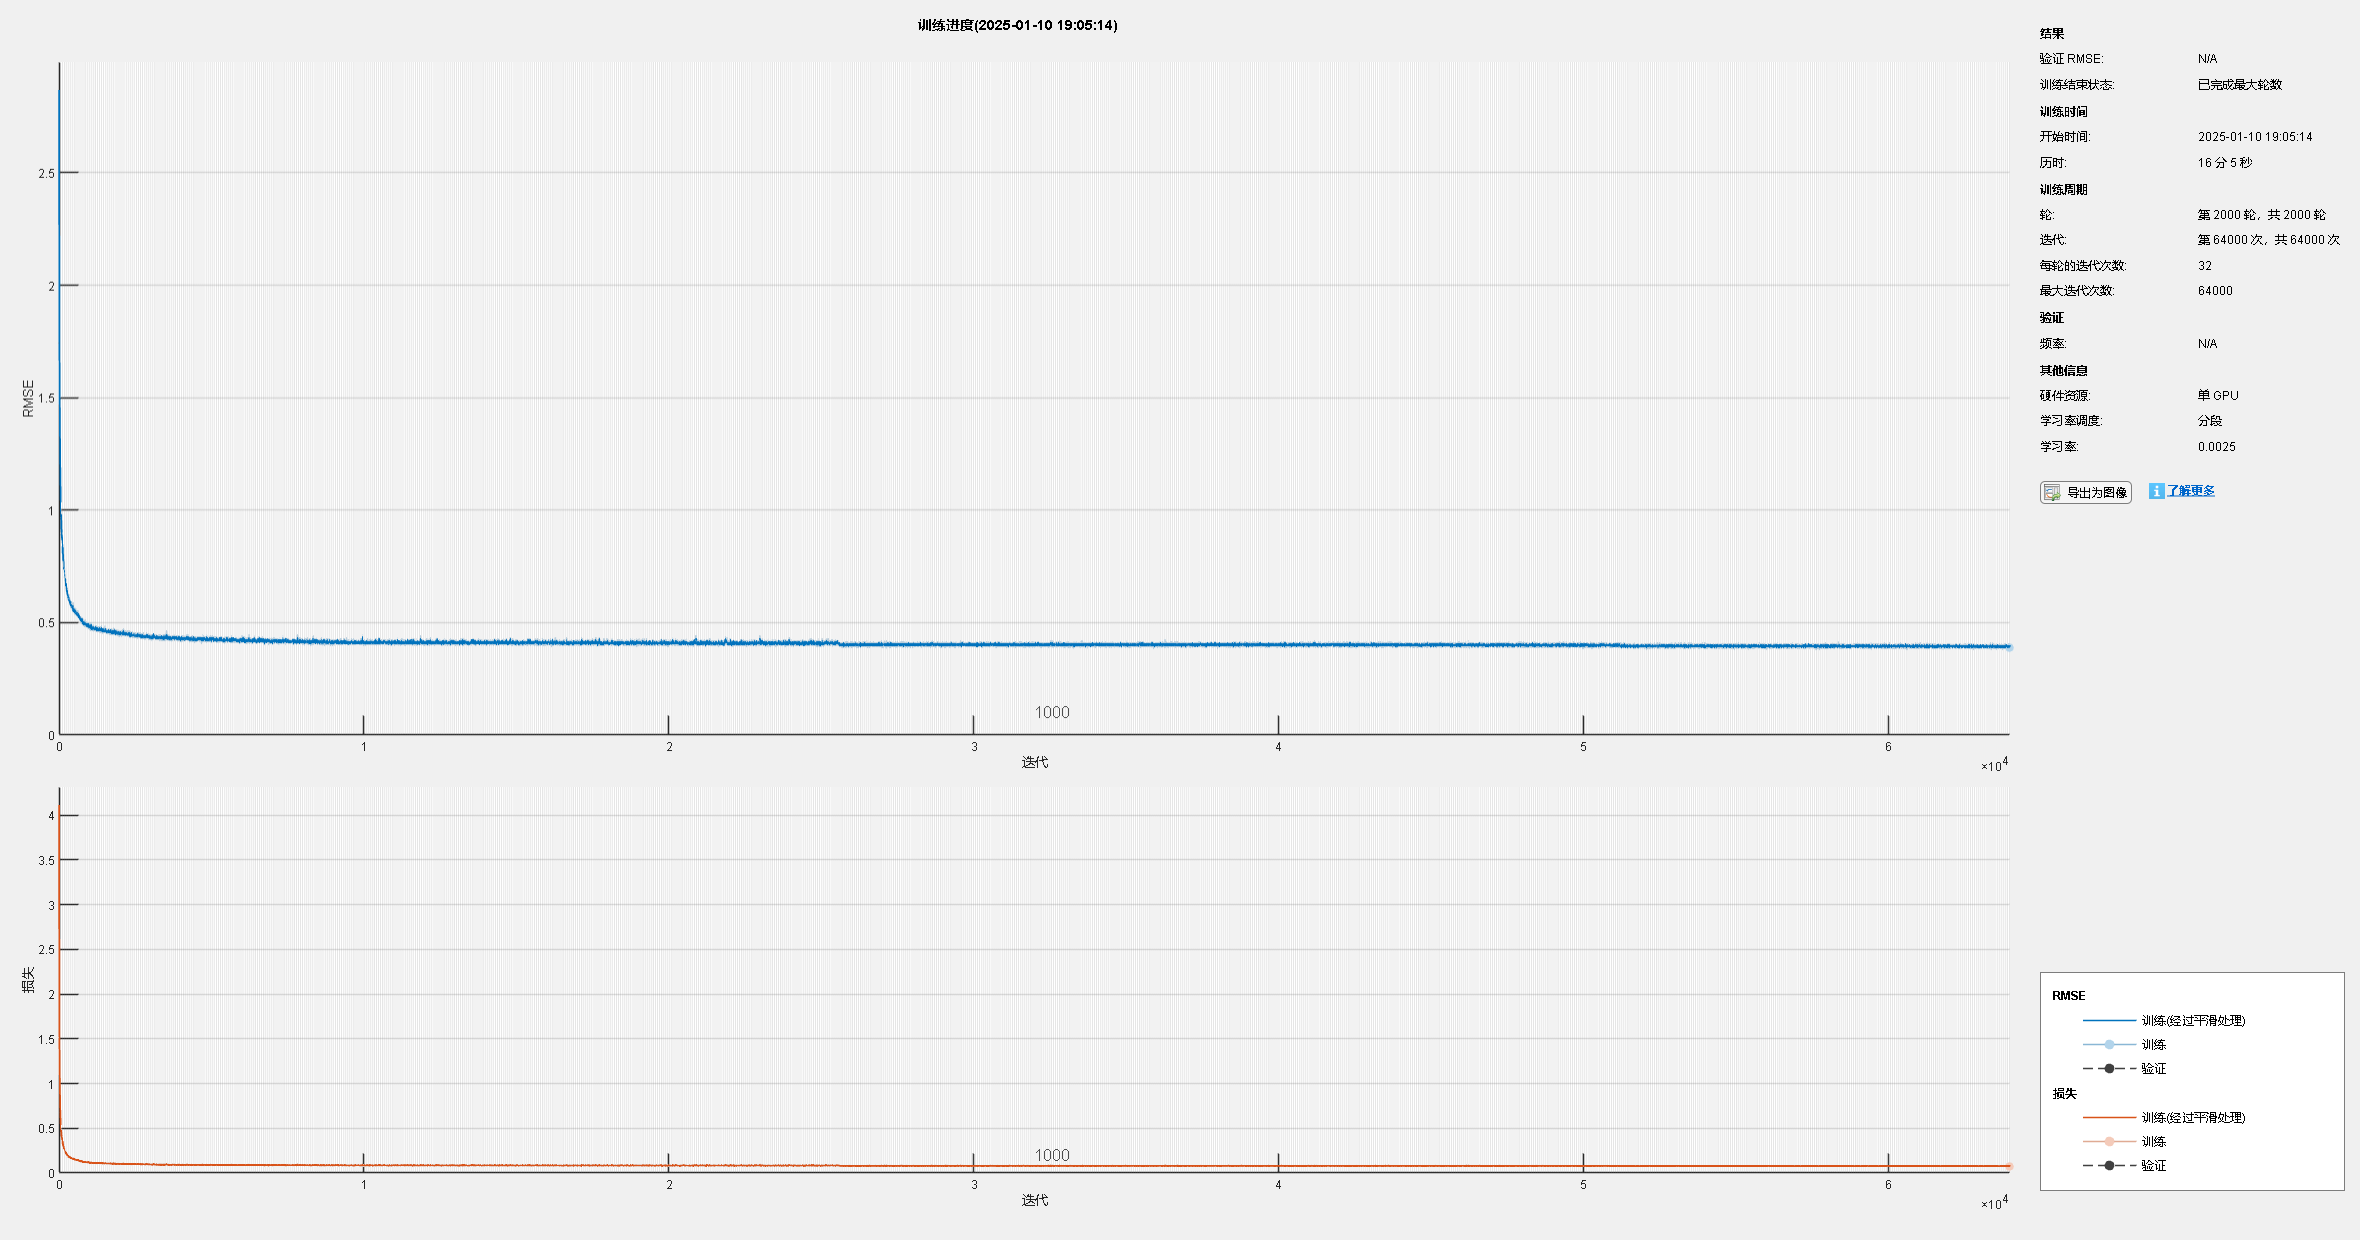

net = trainNetwork(input_train', output_train', layers, options);

### 保存神经网络

save('data\Semi_parameters\RNN_net.mat', 'net');
analyzeNetwork(net);

### 第五步：验证神经网络

t_sim1 = predict(net, input_train');
t_sim2 = predict(net, input_test');
t_sim = double([t_sim1; t_sim2]);

% 均方误差
error1 = sqrt(sum((t_sim1' - output_train).^2) ./ size(output_train, 1));
error2 = sqrt(sum(t_sim2' - output_test).^2 ./ size(output_test, 1));

## VISUALIZATION

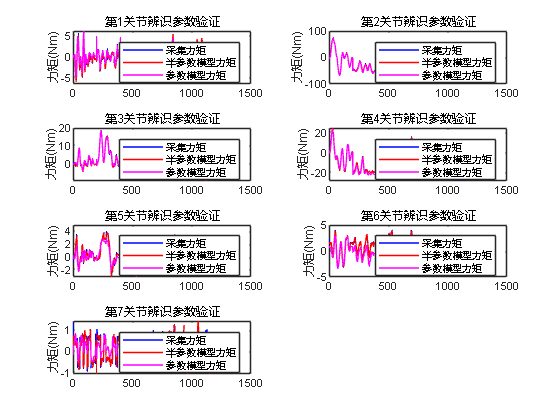

traj_Ts = 0.01;

t = linspace(0, n_sample - 1, n_sample) * traj_Ts;

tiledlayout(4, 2);

for ii = 1:7
    nexttile;
    plot(t, T(:, ii), 'b', 'LineWidth', 1.0); hold on;
    plot(t, T_idy(:, ii) + t_sim(:, ii), 'r', 'LineWidth', 1.0);
    plot(t, T_idy(:, ii), 'm', 'LineWidth', 1.0);
    ylabel('力矩(Nm)');
    legend('采集力矩', '半参数模型力矩', '参数模型力矩');
    title(['第', num2str(ii), '关节辨识参数验证']);
end

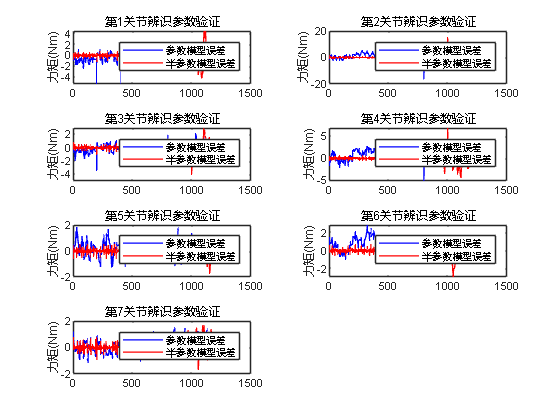

tiledlayout(4, 2);

for ii = 1:7
    nexttile;
    plot(t, T(:, ii) - T_idy(:, ii), 'b', 'LineWidth', 1.0); hold on;
    plot(t, T(:, ii) - T_idy(:, ii) - t_sim(:, ii), 'r', 'LineWidth', 1.0);
    ylabel('力矩(Nm)');
    legend('参数模型误差', '半参数模型误差')
    title(['第', num2str(ii), '关节辨识参数验证'])
end

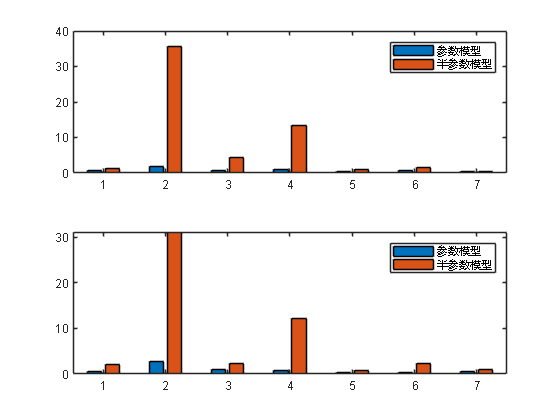

tiledlayout(2, 1);

nexttile;
bar([rmse(T(1:split, :), T_idy(1:split, :), 1); rmse(T(1:split, :), t_sim(1:split, :), 1)]');
legend('参数模型', '半参数模型');

nexttile;
bar([rmse(T(split + 1 : end, :), T_idy(split + 1 : end, :), 1); rmse(T(split + 1 : end, :), t_sim(split + 1 : end, :), 1)]');
legend('参数模型', '半参数模型');

[rmse(T(1:split, :), T_idy(1:split, :), 1); rmse(T(1:split, :), t_sim(1:split, :), 1)]

ans =     0.6521    1.9271    0.6234    0.9657    0.5004    0.8438    0.4733
    1.3782   35.6856    4.2309   13.5012    1.0506    1.6432    0.3980


[rmse(T(split + 1 : end, :), T_idy(split + 1 : end, :), 1); rmse(T(split + 1 : end, :), t_sim(split + 1 : end, :), 1)]

ans =     0.6421    2.8177    0.9088    0.6643    0.4045    0.2859    0.5663
    1.9796   31.1480    2.3509   12.0670    0.8639    2.2215    0.9310
